## Vaccination Schedule

The following script wil seek to find the vaccination schedule that minimizes hospitalizations. ***Updated***

## Initial Parameter Conditions

clear all; clc;

%% Select region and timeframe of data to which model will be fit; specify which contact diary data to use as constraint
region = 'BC';
start_date = 'Nov 1, 2020';
end_date = 'Oct 31, 2050';
Month = 'Dec';
age_cutoff_1 = 50;
age_cutoff_2 = 70;

%% Transmission Parameters
% para = 0.0529; % Fastest growth observed (Sept Matrix)
para = 0.0719; % Fastest growth observed (Dec Matrix)
D_T = 5.0;
D = [D_T,D_T,D_T]; % Mean infectious period for an I in Group i
T_T = 1;
T = [T_T,T_T,T_T]; % Ascertainment fraction of I in Group i 
N = pop_three_groups(age_cutoff_1, age_cutoff_2); % Estimate for population of Group i 
tspan = 1:1:(datenum(end_date)-datenum(start_date)+1); % timespan over which ODE solved

%% Import data and format to yield cumulative reported cases and initial active cases
dataI = readtable('pathway.csv'); % replace with pathway of file storing cumulative reported case data
y1 = init_cond_three_groups_vacc(dataI, start_date, D_T, N, T);

%% Vaccination Parameters
V_T = 0.5; % how much transmission is attenuated 
V_PI = 0.94; % how much protection to infection 
V_PS = 0.97 ; % how much how much protection to severe disease (hospitalization)  
HF = [0.01886908, 0.07689162, 0.2347281]; % hospitalization fraction for each group (calculated from R script)

total_vaccines = 5000000;
days_vaccinating = 200;
vacc_per_day = total_vaccines/days_vaccinating;

% Print summary of simulation details

simulation_summary = {strcat('para=',string(para)); strcat('start_date=',start_date); strcat('end_date=',end_date); strcat('V_T=', string(V_T)); strcat('V_PI=', string(V_PI)); strcat('V_PS=', string(V_PS)); strcat('total_vaccines=', string(total_vaccines)); strcat('days_vaccinating=', string(days_vaccinating)); strcat('vacc_per_day=', string(vacc_per_day))};

## Optimization

% Implicit function which returns cumulative hospitalization count
min_fun = @(vacc_prop, strategy) pred_hosp_vacc(para, T, D, N, V_T, V_PI, V_PS, HF, days_vaccinating, vacc_per_day, vacc_prop, tspan, y1, Month, strategy);
min_fun_print = @(vacc_prop, strategy) pred_hosp_vacc_print(para, T, D, N, V_T, V_PI, V_PS, HF, days_vaccinating, vacc_per_day, vacc_prop, tspan, y1, Month, strategy);
min_fun_print_herd = @(vacc_prop, strategy) pred_hosp_vacc_print_herd(para, T, D, N, V_T, V_PI, V_PS, HF, days_vaccinating, vacc_per_day, vacc_prop, tspan, y1, Month, strategy);

min_fun_total_V_T = @(vacc_prop, strategy, V_T) pred_hosp_vacc_total(para, T, D, N, V_T, V_PI, V_PS, HF, days_vaccinating, vacc_per_day, vacc_prop, tspan, y1, Month, strategy);
min_fun_total_V_PI = @(vacc_prop, strategy, V_PI) pred_hosp_vacc_total(para, T, D, N, V_T, V_PI, V_PS, HF, days_vaccinating, vacc_per_day, vacc_prop, tspan, y1, Month, strategy);
min_fun_total_V_PS = @(vacc_prop, strategy, V_PS) pred_hosp_vacc_total(para, T, D, N, V_T, V_PI, V_PS, HF, days_vaccinating, vacc_per_day, vacc_prop, tspan, y1, Month, strategy);
min_fun_total_para = @(vacc_prop, strategy, para) pred_hosp_vacc_total(para, T, D, N, V_T, V_PI, V_PS, HF, days_vaccinating, vacc_per_day, vacc_prop, tspan, y1, Month, strategy);

**Graphing Epidemic**

% Herd imunnity (assuming same contacts as Nov)
% percent_infected = min_fun_print_herd([0, 0, 0], 'no vacc');

test = [0,0,0];


% 
% % Hospitalizations saved
% 
% 
% hosp_NoVacc = min_fun_print(test, 'no vacc')
% hosp_old = min_fun_print(test, 'oldest')
% hosp_young = min_fun_print(test, 'youngest')
% 
% 
% strategy = 'youngest';
% 
% epi_NoVacc = min_fun(test, strategy);
% 
% plot(tspan, epi_NoVacc(:,[1,9,17]))
% legend('S1', 'S2', 'S3', 'Location', 'Best')
% xlim([0,250])
% 
% plot(tspan, epi_NoVacc(:,[2,10,18]))
% legend('I1', 'I2', 'I3', 'Location', 'Best')
% xlim([0,250])
% 
% plot(tspan, epi_NoVacc(:,[4,12,20]))
% legend('VS1', 'VS2', 'VS3', 'Location', 'Best')
% % xlim([0,250])
% 
% plot(tspan, epi_NoVacc(:,[5,13,21]))
% legend('VI1', 'VI2', 'VI3', 'Location', 'Best')
% % xlim([0,250])
% 
% plot(tspan, epi_NoVacc(:,[7,15,23]))
% legend('H1', 'H2', 'H3', 'Location', 'Best')
% % xlim([0,250])
% 
% 
% 


**Attenuating Transmission (V_T)**

% x=0:0.01:1;
% 
% total_novacc = @(V_T) min_fun_total_V_T(test, 'no vacc', V_T);
% total_old = @(V_T) min_fun_total_V_T(test, 'oldest', V_T);
% total_young = @(V_T) min_fun_total_V_T(test, 'youngest', V_T);
% 
% saved_old = @(V_T) (total_novacc(V_T)-total_old(V_T))/total_novacc(V_T);
% saved_young = @(V_T) (total_novacc(V_T)-total_young(V_T))/total_novacc(V_T);
% 
% 
% y=zeros(1,length(x));
% z=zeros(1,length(x));
% 
% 
% for i=1:length(x)
%     y(i)=100*saved_old(x(i));
%     z(i)=100*saved_young(x(i));
% end
% 
% 
% df=[y;z];
% 
% plot(x,df)
% legend('Oldest First', 'Youngest First', 'Location', 'Best')
% xlabel('\sigma')
% ylabel('Proportion of Hospitalizations Prevented')
% grid on;
% grid minor;
% set(gca, 'FontSize', 18)
% set(gca, 'FontName', 'Arial')
% ytickformat('percentage')
% ylim([40, 100])
% plot_text = strcat('\delta =', {' '}, string(V_PI), '; \tau =', {' '},string(V_PS));
% text(0.70,0.05, plot_text,'Units','normalized', 'FontSize',14, 'FontWeight','normal', "FontName",'Arial')
% 



**Blocking Infection (V_PI)**

% % Explore V_PI
% x=0:0.01:1;
% 
% total_novacc = @(V_PI) min_fun_total_V_PI(test, 'no vacc', V_PI);
% total_old = @(V_PI) min_fun_total_V_PI(test, 'oldest', V_PI);
% total_young = @(V_PI) min_fun_total_V_PI(test, 'youngest', V_PI);
% 
% saved_old = @(V_PI) (total_novacc(V_PI)-total_old(V_PI))/total_novacc(V_PI);
% saved_young = @(V_PI) (total_novacc(V_PI)-total_young(V_PI))/total_novacc(V_PI);
% 
% 
% y=zeros(1,length(x));
% z=zeros(1,length(x));
% 
% 
% for i=1:length(x)
%     y(i)=100*saved_old(x(i));
%     z(i)=100*saved_young(x(i));
% end
% 
% 
% df=[y;z];
% 
% plot(x,df)
% legend('Oldest First', 'Youngest First', 'Location', 'Best')
% xlabel('\delta')
% ylabel('Proportion of Hospitalizations Prevented')
% grid on;
% grid minor;
% set(gca, 'FontSize', 18)
% set(gca, 'FontName', 'Arial')
% ytickformat('percentage')
% ylim([75, 100])
% plot_text = strcat('\tau =', {' '}, string(V_PS), '; \sigma =', {' '},string(V_T));
% text(0.70,0.18, plot_text,'Units','normalized', 'FontSize',14, 'FontWeight','normal', "FontName",'Arial')
% 
% 



**Preventing Hospitalization (V_PS)**

% 
% 
% % Explore V_PS
% x=0:0.01:1;
% 
% total_novacc = @(V_PS) min_fun_total_V_PS(test, 'no vacc', V_PS);
% total_old = @(V_PS) min_fun_total_V_PS(test, 'oldest', V_PS);
% total_young = @(V_PS) min_fun_total_V_PS(test, 'youngest', V_PS);
% 
% saved_old = @(V_PS) (total_novacc(V_PS)-total_old(V_PS))/total_novacc(V_PS);
% saved_young = @(V_PS) (total_novacc(V_PS)-total_young(V_PS))/total_novacc(V_PS);
% 
% y=zeros(1,length(x));
% z=zeros(1,length(x));
% 
% 
% for i=1:length(x)
%     y(i)=100*saved_old(x(i));
%     z(i)=100*saved_young(x(i));
% end
% 
% 
% df=[y;z];
% 
% plot(x,df)
% legend('Oldest First', 'Youngest First', 'Location', 'Best')
% xlabel('\tau')
% ylabel('Proportion of Hospitalizations Prevented')
% grid on;
% grid minor;
% set(gca, 'FontSize', 18)
% set(gca, 'FontName', 'Arial')
% ytickformat('percentage')
% ylim([75, 100])
% plot_text = strcat('\delta =', {' '}, string(V_PI), '; \sigma =', {' '},string(V_T));
% text(0.70,0.05, plot_text,'Units','normalized', 'FontSize',14, 'FontWeight','normal', "FontName",'Arial')
% 



**Contact Behaviour**

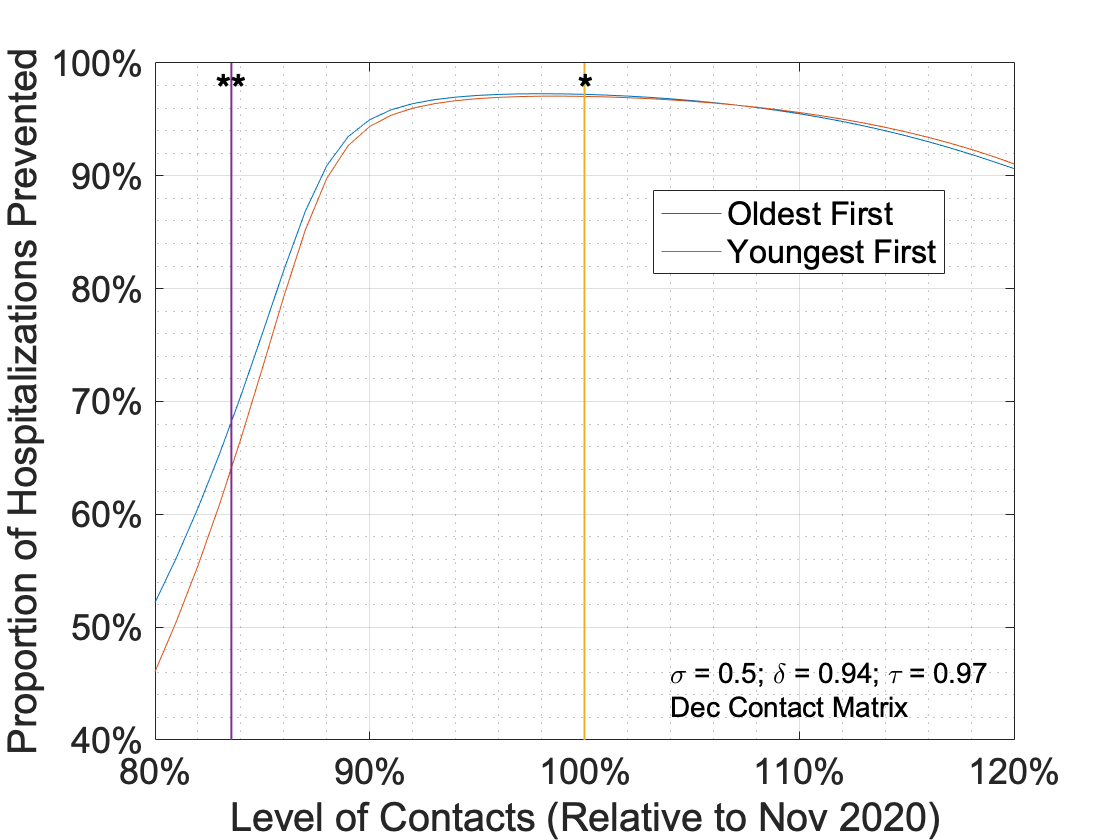

% Proportion of Hospitalizations Saved

total_novacc = @(para) min_fun_total_para(test, 'no vacc', para);
total_old = @(para) min_fun_total_para(test, 'oldest', para);
total_young = @(para) min_fun_total_para(test, 'youngest', para);
saved_old = @(para) (total_novacc(para)-total_old(para))/total_novacc(para);
saved_young = @(para) (total_novacc(para)-total_young(para))/total_novacc(para);


range = 80:1:120; 

if string(Month) == 'Sept'
    x=range/100*0.0529;
elseif string(Month) == 'Dec'
    x=range/100*0.0719;
end

y=zeros(1,length(x));
z=zeros(1,length(x));
for i=1:length(x)
    y(i)=100*saved_old(x(i));
    z(i)=100*saved_young(x(i));
end
df1=[y;z];


if string(Month) == 'Sept'
    plot(range,df1)
    legend('Oldest First', 'Youngest First', 'Location', 'Best')
    xlabel('Level of Contacts (Relative to Nov 2020)')
    ylabel('Proportion of Hospitalizations Prevented')
    grid on;
    grid minor;
    set(gca, 'FontSize', 18)
    set(gca, 'FontName', 'Arial')
    ytickformat('percentage')
    xtickformat('percentage')
    ylim([40, 100])
    xlim([range(1), range(length(range))])
    plot_text1 = strcat('\sigma =', {' '},string(V_T), '; \delta =', {' '}, string(V_PI), '; \tau =', {' '}, string(V_PS));
    text(0.60,0.10, plot_text1,'Units','normalized', 'FontSize',14, 'FontWeight','normal', "FontName",'Arial')
    plot_text2 = strcat(Month, {' '}, 'Contact Matrix');
    text(0.60,0.05, plot_text2,'Units','normalized', 'FontSize',14, 'FontWeight','normal', "FontName",'Arial')
    hold on
    plot([100; 100], [ylim], 'LineWidth',1)
    hold off
    text([100],[98], {'*'}, 'FontSize',18, 'FontWeight','bold','HorizontalAlignment',"center")
    hold on
    plot([83.55387524; 83.55387524], [ylim], 'LineWidth',1)
    hold off
    legend('Oldest First', 'Youngest First', 'Location', 'Best')
    text([83.55387524],[98], {'**'}, 'FontSize',18, 'FontWeight','bold','HorizontalAlignment',"center")
elseif string(Month) == 'Dec'
    plot(range,df1)
    legend('Oldest First', 'Youngest First', 'Location', 'Best')
    xlabel('Level of Contacts (Relative to Nov 2020)')
    ylabel('Proportion of Hospitalizations Prevented')
    grid on;
    grid minor;
    set(gca, 'FontSize', 18)
    set(gca, 'FontName', 'Arial')
    ytickformat('percentage')
    xtickformat('percentage')
    % ylim([75, 100])
    xlim([range(1), range(length(range))])
    plot_text1 = strcat('\sigma =', {' '},string(V_T), '; \delta =', {' '}, string(V_PI), '; \tau =', {' '}, string(V_PS));
    text(0.60,0.10, plot_text1,'Units','normalized', 'FontSize',14, 'FontWeight','normal', "FontName",'Arial')
    plot_text2 = strcat(Month, {' '}, 'Contact Matrix');
    text(0.60,0.05, plot_text2,'Units','normalized', 'FontSize',14, 'FontWeight','normal', "FontName",'Arial')
    hold on
    plot([100; 100], [ylim], 'LineWidth',1)
    hold off
    text([100],[98], {'*'}, 'FontSize',18, 'FontWeight','bold','HorizontalAlignment',"center")
    hold on
    plot([83.55387524; 83.55387524], [ylim], 'LineWidth',1)
    hold off
    legend('Oldest First', 'Youngest First', 'Location', 'Best')
    text([83.55387524],[98], {'**'}, 'FontSize',18, 'FontWeight','bold','HorizontalAlignment',"center")
end